# Implementation Structures for IIR and FIR Systems (150 Points)

Dear Students, 

Welcome to Lab 4! In this lab, you will implement IIR and FIR filters using several different structures.  

### **References: **

-  Chapter 6, Section 0 - 5 of "A.V. Oppenheim and R. W. Schafer, Discrete-Time Signal Processing, Prentice Hall, 2nd Edition".

-  "Week-7 Video-3.mp4" and "Week-7 Video-4.mp4" of EE321 Course. 

-  [https://spinlab.wpi.edu/courses/ece503_2014/week8.html](https://spinlab.wpi.edu/courses/ece503_2014/week8.html)

## IIR Systems **(100 Points)**

NOTE: I had recorded sound for 5 secs andwitll display "Recording Starts" when it begins. after signal is stored once just comment the lines if running the code again to make it easier.

#### **Question 1:   **

Name IIR filter implementation structures that you have studied. 

ANS: Direct Form 1 and 2, cascade form, cannonical form, transposed form and parallel form.

Now, consider the following filter transfer function: 

                                                    $H(z) =\frac{1+\frac{5}{6}z^{-1}+\frac{1}{6}z^{-2} }{1+z^{-1}+\frac{1}{2}z^{-2}}$ .............................................................   (1)

-  What are the $b$ and $a$ coefficients  in (1)? (Find by inspection)

% coeffiencits of transfer function 
b = [1 5/6 1/6];   %Numerator
a = [1 1 1/2];     %Denominator

- Obtain the impulse response of the above filter in (1) (user [impz](https://in.mathworks.com/help/signal/ref/impz.html)) 

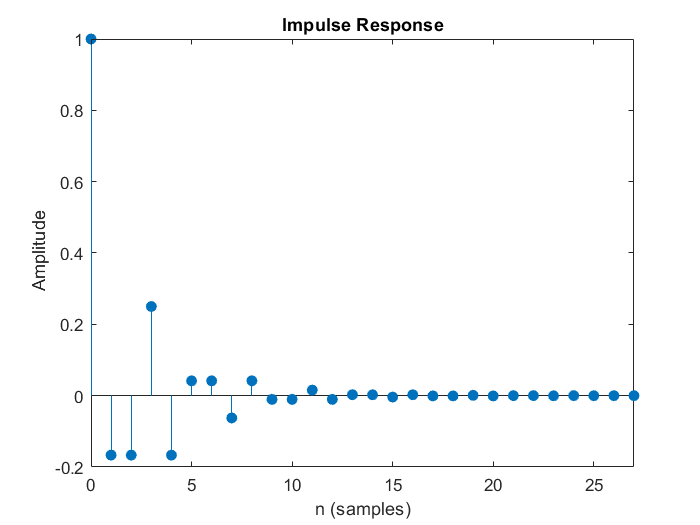

% impulse response
h = impz(b,a);
impz(b,a);

- Obtain the magnitude response of the filter in (1) (use [freqz](https://in.mathworks.com/help/signal/ref/freqz.html))

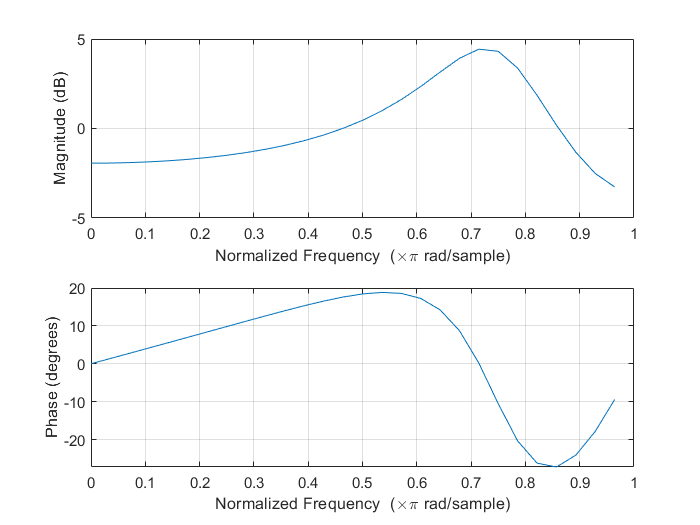

% Magnitude response
 freqz(b,a,length(h))

-  Obtain the pole-zero plot of (1) (use [zplane](https://in.mathworks.com/help/signal/ref/zplane.html)) 

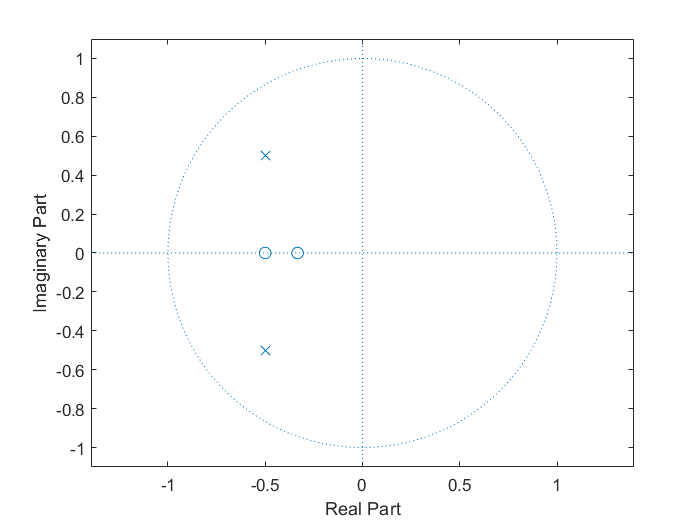

% pole-zero plot
zplane(b,a)

- Is the filter stable?                                                                                                                                                                                                                                                                    

           ANS: Yes, as all poles(real or complex) are inside the unit circle.

- Why are complex poles appearing in complex-conjugate pairs?

           ANS: Complex poles are appearing in conjugate pairs because they both have same magnitude and negative of angles.(which cancel each other on multiplication giving real product)ie. **real transfer function.**

- Why is it an IIR filter? 

           ANS: They are Infinite Impulse Response (IIR) filters which usually use relational transfer functions and have closed loops. They can get unstable at times but need lesser coefficients than FIR as they are more general form for any LTI system.

Now speak and record your voice or music for 5 seconds (see [audiorecorder](https://in.mathworks.com/help/matlab/ref/audiorecorder.html) and[ ](https://in.mathworks.com/matlabcentral/answers/357862-real-time-recording-audio-filtering)[https://in.mathworks.com/matlabcentral/answers/357862-real-time-recording-audio-filtering).](https://in.mathworks.com/matlabcentral/answers/357862-real-time-recording-audio-filtering).) Assign the recorded sequence to a variable named 

rec = audiorecorder;  %We record the sound once and save it in myRecordedSignal
disp('Recording Starts')
recordblocking(rec, 5);
disp('Recording Ends');
myRecordedSignal = getaudiodata(rec);

%%%%%%%%%%%%%__comment the above part after
%recording signal once to keep it in memory.
x=myRecordedSignal; %We assign it to variable x for using different finters on it.
Fs=8000 ; %When nothing is specified audiorecorder takes 8000 Hz and 8 Bits per sample.

In the following, you will filter $myRecordedSignal$ with the filter in (1) using  different IIR filter structures.

### Direct Form - I Structure:

Now, given, $myRecordedSignal$ signal,  write a code to compute the output using Direct Form - I structure (see the below figure).  

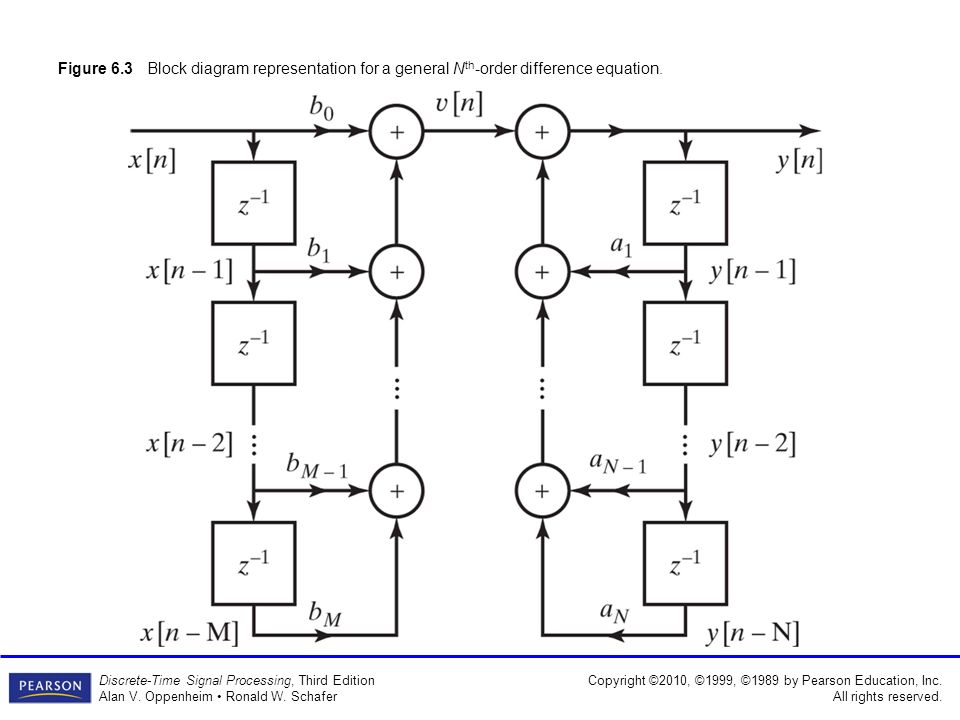

-   Before you code, write the difference equation relation between input sequence, $x[n]$ and output sequence, $y[n]$.          

              ANS (completed for you) :               $y[n] = -y[n-1]-0.5y[n-2]+x[n]+\frac{5}{6}x[n-1]+\frac{1}{6}x[n-2]$                            

% Completed for you. 
y =  zeros(1, length(x)+2); 

for n =  3: length(x)    % We start with index 3  
    y(n) = -1*y(n-1)-0.5*y(n-2)+x(n)+(5/6)*x(n-1)+(1/6)*x(n-2); 
    
end
result=y(3:end);

- In the above code snippet, why are we starting the *for-loop* at index 3? 

            ANS .This is because the difference equation uses two past output y[n-1] and y[n-2] and past inputs x[n-1] and x[n-2] to calculate the current output. For the past outputs to be in index we have to start with index 3 so that even the starting value has 2 past stored values. That way we will not go out of bound for array while trying to get past values . And thats why our result is stored from index 3 to index length(x)+2 in y and not from beginning.

- How many multiplications and delay elements are required for the Direct Form I implementation?

            ANS: 7 multiplications with 6 delay elements 

- Now, listen to the original and filtered signal (use [sound](https://in.mathworks.com/help/matlab/ref/sound.html))   

 % play your signals here, Use appropriate sampling frequency

 sound(result,Fs);

- Now, compute and plot magnitude responses of the original and filtered signals  (Write a function MagnitudeResponse(x, Fs)  so that you can reuse it)

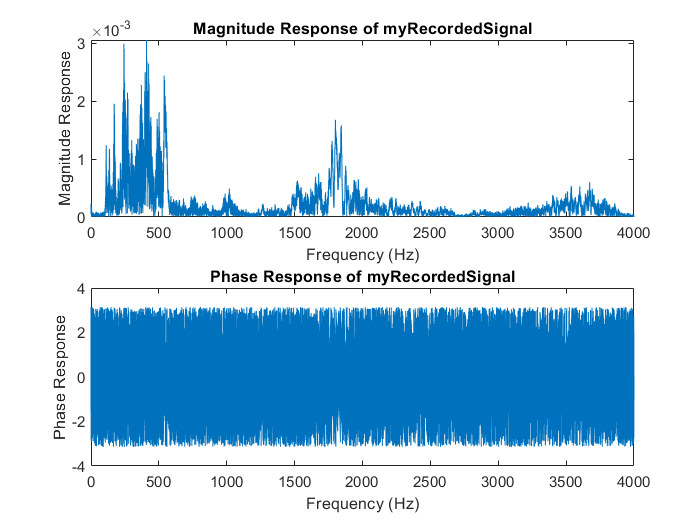


%  MagnitudeResponse(x, Fs, SignalName) % This function needs to be defined at the end of the
%  file (Matlab requires you to do that). A skeleton is provided. 

MagnitudeResponse(myRecordedSignal, Fs, 'myRecordedSignal');  

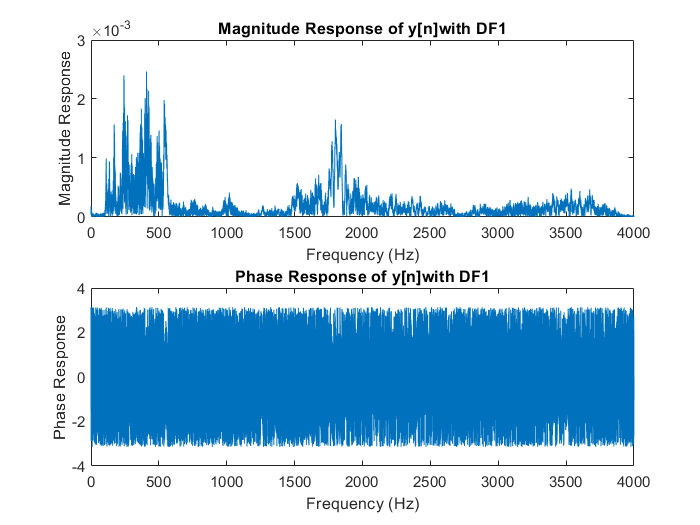

MagnitudeResponse(result, Fs, 'y[n]with DF1');  

- Write your observations  related to above magnitude responses. 

#### **         ANS :   The magnitude responces look similar just the filtered signal has slight scaling which results in its magnitude slightly smaller than that of recorded signal.**

### Direct Form - II Structure:

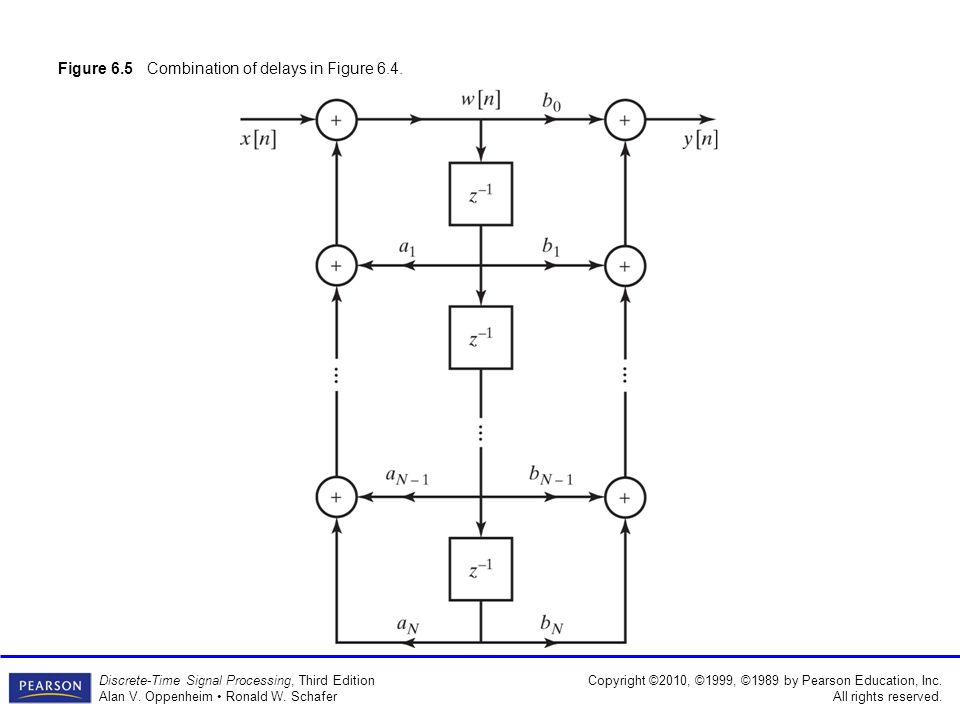

- Before you code, write down difference equations required to implement (1) in Direct Form - II. 

            ANS:  $$$y[n]=w[n]+w[n-1]+0.5w[n-2] \\  w[n]=x[n]-\frac{5}{6}x[n-1]-\frac{1}{6}x[n-2]\\
$

- How many multiplications and delay elements are required for the Direct Form I implementation?

            ANS:   4 multliplications and 2 delay elements are required.

- Code:

% Write your code here
y =  zeros(1, length(x)+2); 
w =  zeros(1, length(x)+2);

for n =  3: length(x)    % We start with index 3
    w(n)=x(n)-(5/6)*x(n-1)-(1/6)*x(n-2);
    y(n) = w(n)+w(n-1)+w(n-2); 
    
end
result=y(3:end);
MagnitudeResponse(myRecordedSignal, Fs, 'myRecordedSignal');  

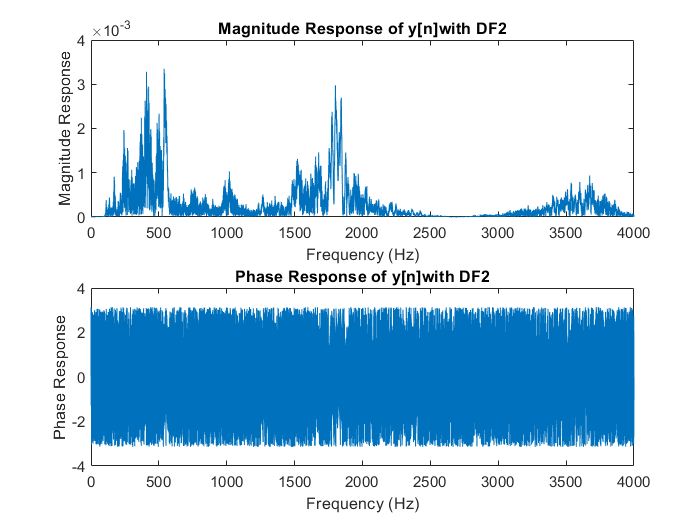

MagnitudeResponse(result, Fs, 'y[n]with DF2'); 

%sound(result,Fs); %Its similar to original too

### Cascade Form Structure: 

#### First-Order Sections

-    Implement the filter in (1) in cascade form structure with first-order sections

                -  Write down difference equations required for the implement, here: 

                   
$$H(z) =\frac{[1+\frac{1}{2}z^{-1}][\frac{1}{3}+z^{-1}] }{[1+(0.5-0.5i)z^{-1}][1+(0.5+0.5i)z^{-1}]}\\
w1[n]=x[n]+\frac{1}{2}x[n-1] \\
w2[n]=w1[n]+\frac{1}{3}w1[n-1]\\
w3[n]=w2[n]-(0.5-0.5i)w2[n-1]\\
y[n]=w3[n]-(0.5+0.5i)w3[n-1]$$
     

-   Code:                 

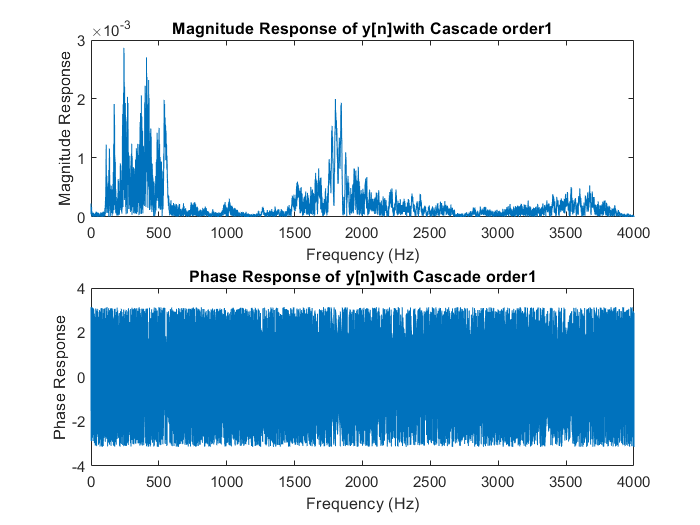

% First-order sections
y =  zeros(1, length(x)+1);  %To implement cascade we will need many intermediate steps.
w1= zeros(1, length(x)+1);
w2= zeros(1, length(x)+1);
w3= zeros(1, length(x)+1);

for n =  2: length(x)    % We start with index 2 as its first order  
    w1(n) = x(n)+(1/2)*x(n-1);
    w2(n)=w1(n)+(1/3)*w1(n-1);
    w3(n)=w2(n)-(.5-.5*1i)*w2(n-1); %We got some complex values too
    y(n)=w3(n)-(.5+.5*1i)*w3(n-1); 
    
end
result=y(2:end);
%MagnitudeResponse(myRecordedSignal, Fs, 'myRecordedSignal');  %Its plotted
%%earlier so no need to plot everytime.
MagnitudeResponse(result, Fs, 'y[n]with Cascade order1'); 

%sound(real(result),Fs); %Its real part is similar to original too

####  Second-Order Sections

-    Implement the filter in (1) in cascade form structure with second-order sections

                -  Write down difference equations required for the implementation, here: 

                   
$$H(z) =\frac{[1+\frac{1}{2}z^{-1}][\frac{1}{3}+z^{-1}] }{[1+(0.5-0.5i)z^{-1}][1+(0.5+0.5i)z^{-1}]}\\
w1[n]=x[n]+\frac{1}{2}x[n-1] +\frac{1}{3}x[n-2]\\
y[n]=w1[n]-(0.5-0.5i)w1[n-1]-(0.5+0.5i)w1[n-2]$$
    

-    Code:

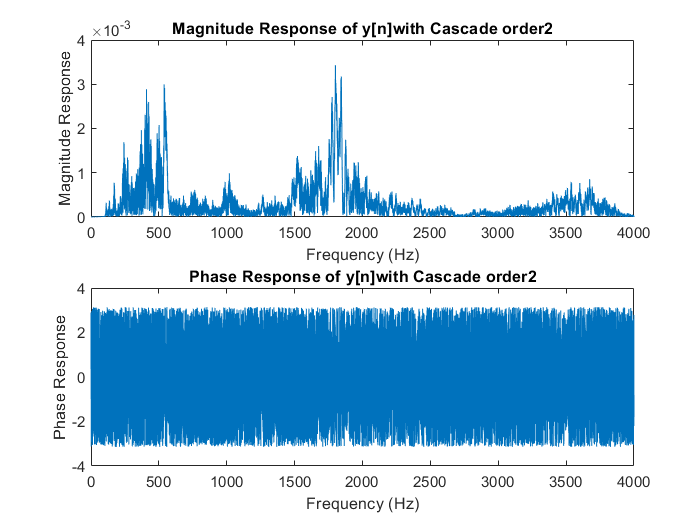

% Second-order sections
y =  zeros(1, length(x)+2);  %To implement cascade we will need one mid step.
w1= zeros(1, length(x)+2);

for n =  3: length(x)    % We start with index 3 as its second order  
    w1(n) = x(n)+(1/2)*x(n-1)+(1/3)*x(n-2);
    y(n)=w1(n)-(.5-.5*1i)*w1(n-1)-(.5+.5*1i)*w1(n-2); %We got some complex values too
    
end
result=y(3:end);
%MagnitudeResponse(myRecordedSignal, Fs, 'myRecordedSignal'); %Its plotted
%%earlier so no need to plot everytime. 
MagnitudeResponse(result, Fs, 'y[n]with Cascade order2'); 

%sound(real(result),Fs); %Its real part is similar to original too


- Compare your first-order and second order section cascaded implementations, in terms of number of real and complex multiplications, number of memory elements. Why is second-order sections (SOS) preferred? 

            ANS: Clearly second order cascaded implementation uses much less memory elements (2)while first order uses(4). 

The multiplications are 5 (2 complex)while addition is 6 in second order cascaded implementation  while for first order also has 5 multiplications and 6 additions.

Seconf-order is preferred as it needs less number of storage elements with similar computation power so is easier to implement in practice.

### Parallel Form Structures:

- Express the transfer function in (1) to suit the parallel  form implementation

               ANS: As factors of demominator(Poles) were complex so we choose second order implementation to make things easier.

      
$$H(z) =\frac{1}{3}+\frac{\frac{2}{3}+\frac{1}{2}z^{-1} }{1+z^{-1}+\frac{1}{2}z^{-2}}$$


- Write down difference equations required for parallel  form implementation here. 

               ANS:  we take w1 at the point where the delay elements are connected in the corresponding diagram.     

                        
$$w1[n]=\frac{2}{3}x[n]-\frac{1}{2}x[n-1] \\
y[n]=\frac{1}{3}x[n]+w1[n]+w1[n-1]+\frac{1}{2}w1[n-2]$$
       

- Code: 

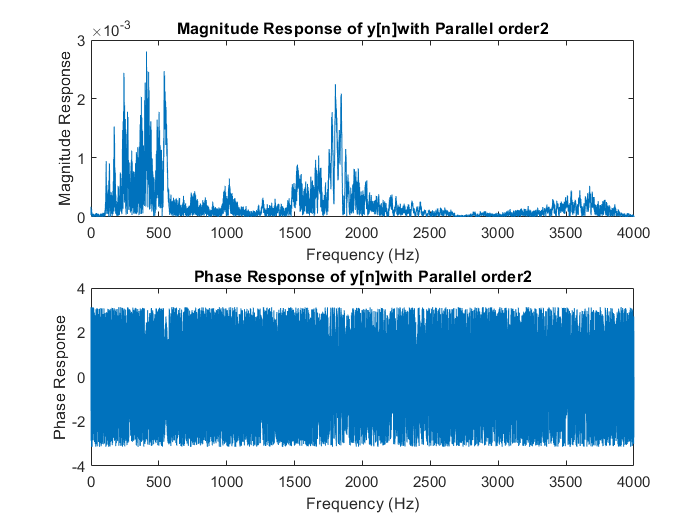

% Write your code here 
y =  zeros(1, length(x)+2);  %To implement cascade we will need one mid step.
w1= zeros(1, length(x)+2);

for n =  3: length(x)    % We start with index 3 as its second order  
    w1(n) = (2/3)*x(n)-(1/2)*x(n-1);
    y(n)=(1/3)*x(n)+w1(n)+w1(n-1)+(1/2)*w1(n-2); %By taking order 2 we got rid of complex poles making it simpler.
    
end
result=y(3:end);
%MagnitudeResponse(myRecordedSignal, Fs, 'myRecordedSignal');   %Its plotted
%%earlier so no need to plot everytime.
MagnitudeResponse(result, Fs, 'y[n]with Parallel order2'); 

%sound(real(result),Fs); %Its real part is similar to original too

- How many multiplications and memory elements are required? 

It needs 2 memory elements with 5 multiplications.

### Transposed Form Structures:      

- Draw the transposed form  of your Direct Form  II structure of (1)

          ANS: 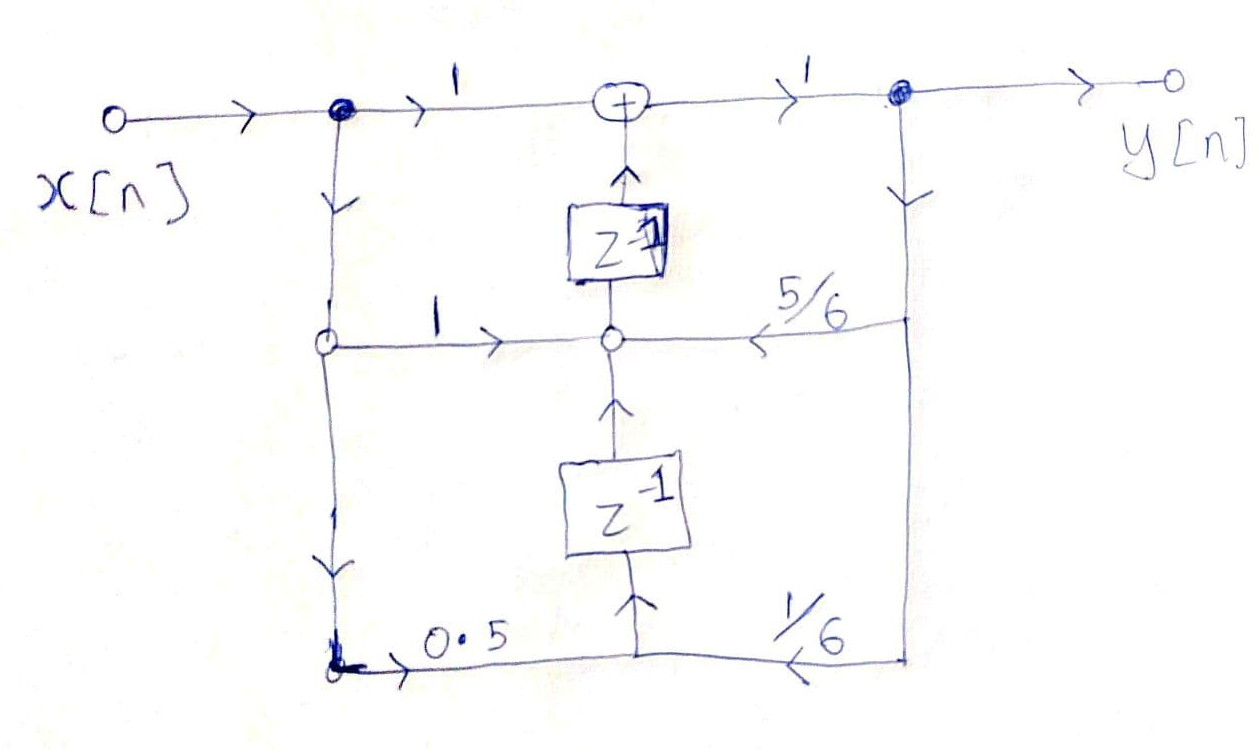

- Write down the corresponding difference equations

            ANS:    $y[n]=x[n]+x[n-1]+0.5x[n-2] -\frac{5}{6}y[n-1]-\frac{1}{6}y[n-2]\  
$

-  Code

% Write your code here 
y =  zeros(1, length(x)+2);  %We need 2 additional space for past data.

for n =  3: length(x)    % We start with index 3
    y(n)=x(n)+x(n-1)+0.5*x(n-2)-(5/6)*y(n-1)-(1/6)*y(n-2);
    
end
result=y(3:end);
MagnitudeResponse(myRecordedSignal, Fs, 'myRecordedSignal');  

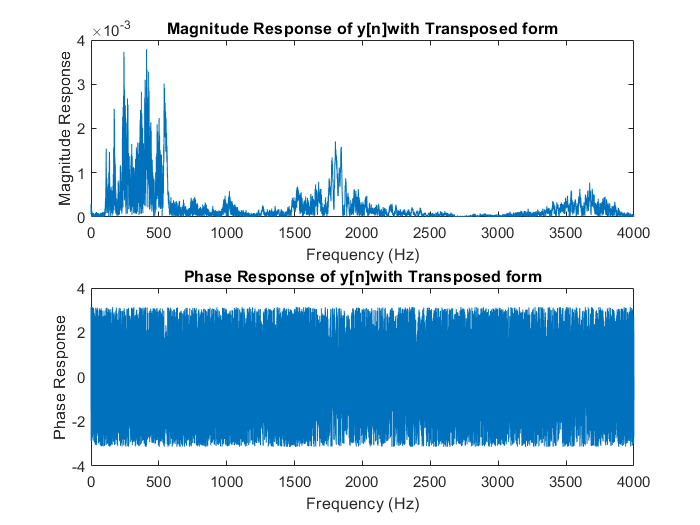

MagnitudeResponse(result, Fs, 'y[n]with Transposed form'); 

%sound(result,Fs); %Its similar to original too

### Lattice Form Structures (OPTIONAL) 

- Draw the lattice form of (1). To get lattice coefficients, you can use *tf2latc*

- Implement the lattice structure 

% Code here (OPTIONAL)

###  General Questions: 

- (True or False?)  The number of delay elements required for the direct form-I implementation of an IIR filter is strictly greater than that for the direct form -II implementation.  True

- True or False? The number of multiply and accumulate operations in the direct form - II and transpose forms are the same.True 

- (True or False?): In a filter with complex conjugate poles and zeros, second-order-sections are used so that multiplications are always real.   True 

- (True or False?): In the transposed structures, input values are not stored but intermediate values are stored.  False

- (True or False?): Transposed structures require more number of multiplications and memory elements compared to their original counterparts. False

- Write any of your observations here, that we not asked in any of the questions above. 

Observations: I felt all the magnitude plots were scaled by a factor slightly smaller than 1 .

## FIR Filters **(50 Points)**

- Name different FIR structures that you have studied. 

            ANS: Direct form, Cascade form, Lattice structure.

In this section, we are interested in two forms only

- Structures for Linear-Phase FIR Systems

- Lattice Structures

### Structures for Linear-Phase FIR Systems

Consider $H(z) = 1+2z^{-1}+3z^{-2}+2z^{-3}+z^{-4}$. 

- Draw the Direct Form structure with a minimum number of multiplications for implementing the $H(z)$ above. 

            ANS Multiplications needed= 3 (as h[4-n]=h[n]),  additions needed=4, 4 memory elements are rquired.

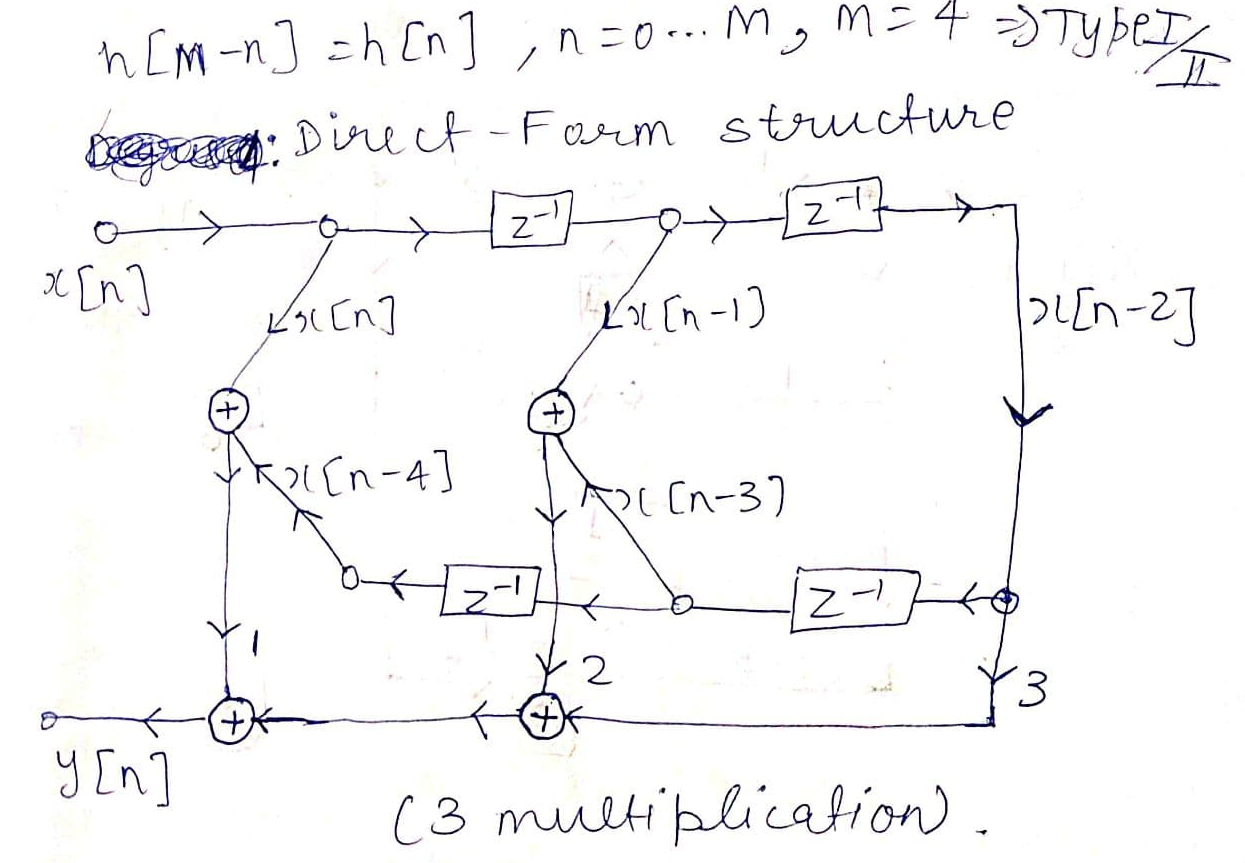

- Write down corresponding difference equations

            ANS $y[n]=(x[n]+x[n-4])+2(x[n-1]+x[n-3])+3x[n-2] 
$

- Code: 

% Write your code here. Use myRecordedSignal as the input for your filter. 
y =  zeros(1, length(x)+4);  %We need 4 additional space for past data.

for n =  5: length(x)    % We start with index 5
    y(n)=(x(n)+x(n-4))+2*(x(n-1)+x(n-3))+3*x(n-2);
    
end
result=y(5:end);
MagnitudeResponse(myRecordedSignal, Fs, 'myRecordedSignal');  
MagnitudeResponse(result, Fs, 'y[n]using linear phase FIR'); 
sound(result,Fs); %Its not similar but can detect the same words thought its louder than origional.

### Lattice Structures

Consider $H(z) = 1+\frac{3}{2}z^{-1}-z^{-2}+\frac{3}{4}z^{-3}+2z^{-4}$. 

- Draw the lattice structure for implementing the $H(z)$ above. 

            ANS 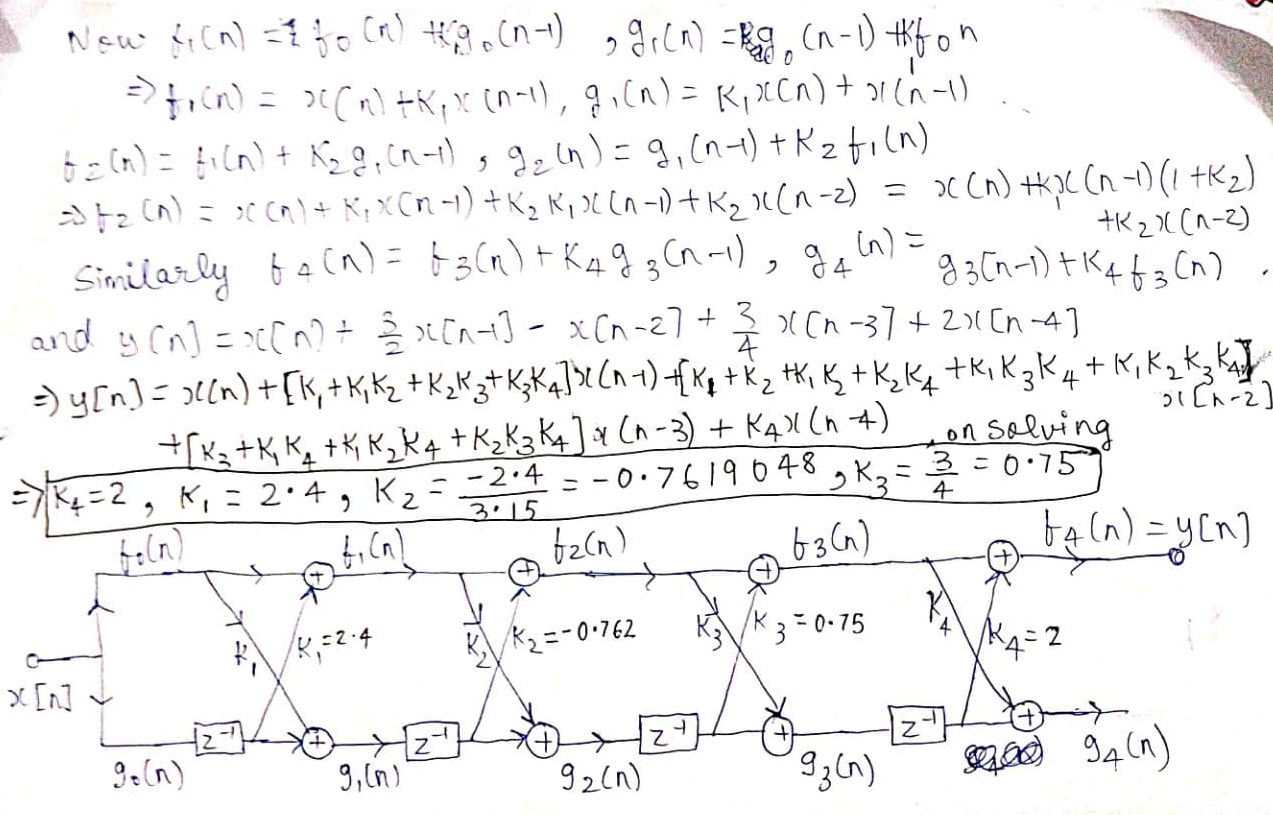

- Compute lattice coefficients  (manually).  (Use tf2lact for verification)

            ANS: K1=2.4, K2=$\frac{-2.4}{3.15}=-0.7619048\sim-0.762$, K3=0.75, K4=2.

- Implement the above $H(z)$using the lattice form structure. 

num=[1 3/2 -1 3/4 2]; %The given transfer function
H=filt(num,1);

%Verifying coefficients
latcoeff=tf2latc(num);
fprintf("Lattice coefficients using tf2latc are ");
disp(latcoeff);
% Write your code here. Use myRecordedSignal as the input for your filter. 

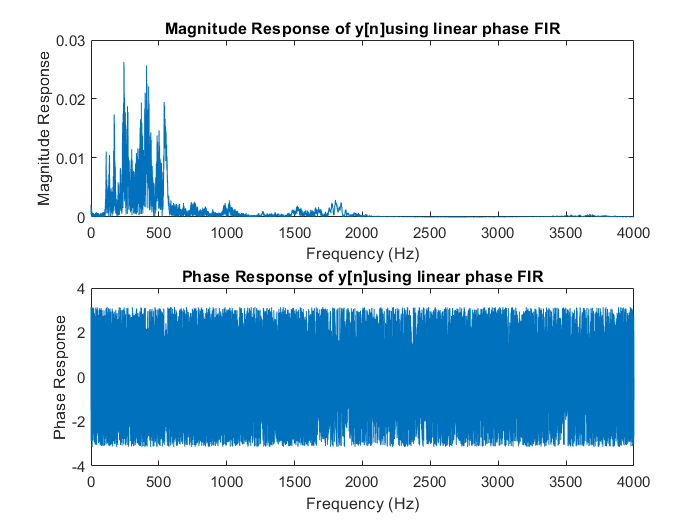

%We only compute the minum things required here but practically everything will

%be calculated .
y =  zeros(1, length(x)+1);  %We need only 1 additional space for past data.
f1 =  zeros(1, length(x)+1);
g1 =  zeros(1, length(x)+1);
f2 =  zeros(1, length(x)+1);
g2 =  zeros(1, length(x)+1);
g3 =  zeros(1, length(x)+1);
f3 =  zeros(1, length(x)+1);
K1=2.4;  %Defining the coefficients of Lattice.
K2=-2.4/3.15;
K3=0.75;
K4=2;
for n =  2: length(x)    % We start with index 2
    f1(n)=x(n)+K1*x(n-1);   %Stimulating/implementing the lattice
    g1(n)=x(n-1)+K1*x(n);
    f2(n)=f1(n)+K2*g1(n-1);

Lattice coefficients using tf2latc are 

    g2(n)=g1(n-1)+K2*f1(n);

    2.4000
   -0.7619
    0.7500
    2.0000



    f3(n)=f2(n)+K3*g2(n-1);
    g3(n)=g2(n-1)+K3*f2(n);
    y(n)=f3(n)+K4*g3(n-1);
    
end
result=y(2:end);
MagnitudeResponse(myRecordedSignal, Fs, 'myRecordedSignal');  
MagnitudeResponse(result, Fs, 'y[n]using linear Lattice structures'); 
sound(result,Fs); %Its similar to original too

####  General Questions: 

- Write down observations you have made. 

Sometimes the sound gets louder in FIR section as the magnitude got higher than origional(scaling >1)  in case of Direct form but its amplitude is almost same in case of Lattice.

## Function Definitions:

function MagnitudeResponse(x, Fs, SignalName)

% COMPLETE THE CODE HERE TO COMPUTE THE MAGNITUDE RESPONSE OF x   l
Fn = Fs/2;                  % Nyquist Frequency
y = fft(x);                 %fourier transform
m = 2*abs(y)/length(x);
f = linspace(0, 1, fix(length(y)/2)+1)*Fn;   %Frequencies to plot which is in one period of sample
Iv = 1:length(f);                              % Index Vector
figure 
subplot(2,1,1)
plot(f,m(Iv))
title(['Magnitude Response of ' SignalName])
xlabel('Frequency (Hz)')
ylabel('Magnitude Response')
hold on
subplot(2,1,2)
plot(f,angle(y(Iv)))

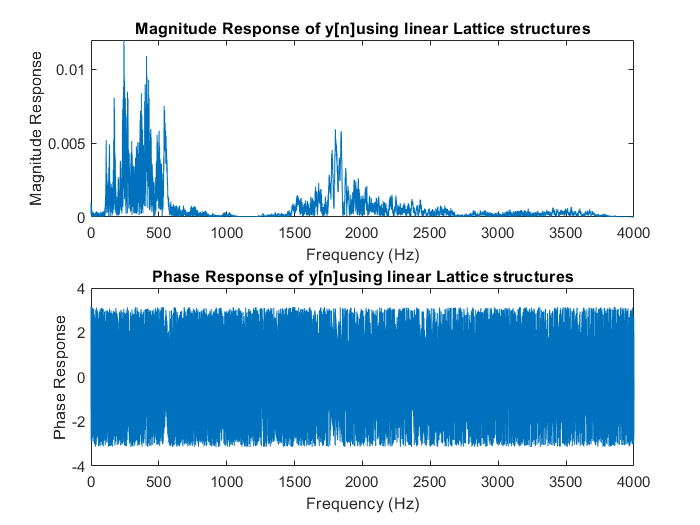

hold off;

title(['Phase Response of '  SignalName])
xlabel('Frequency (Hz)')
ylabel('Phase Response')

end

### Thank you!